%% Fresh network
clear net
net = WirelessNetwork;

%% 3-cell reuse before sectorization
net.channel_sets = [6 6 6];
sum(net.channel_sets)

ans = 18


%% Add base stations manually (unsectorized)
net.AddBase(100+100i,1,35);
net.AddBase(200+100i,2,35);
net.AddBase(300+100i,3,35);
net.AddBase(400+100i,1,35);
net.AddBase(500+100i,2,35);

net.AddBase( 50+200i,2,35);
net.AddBase(150+200i,3,35);
net.AddBase(250+200i,1,35);
net.AddBase(350+200i,2,35);
net.AddBase(450+200i,3,35);

net.AddBase(100+300i,3,35);
net.AddBase(200+300i,1,35);
net.AddBase(300+300i,2,35);
net.AddBase(400+300i,3,35);
net.AddBase(500+300i,1,35);

net.AddBase( 50+400i,1,35);
net.AddBase(150+400i,2,35);
net.AddBase(250+400i,3,35);
net.AddBase(350+400i,1,35);
net.AddBase(450+400i,2,35);

net.AddBase(100+500i,2,35);
net.AddBase(200+500i,3,35);
net.AddBase(300+500i,1,35);
net.AddBase(400+500i,2,35);
net.AddBase(500+500i,3,35);

%% Now sectorize into 3 sectors
net.Sectorize(3);


net.channel_sets = [2 2 2 2 2 2 2 2 2];


% Show the network object
net

net =   WirelessNetwork with properties:

           bs_locations: [25×1 double]
            bs_channels: [25×3 double]
           bs_power_dBm: [25×3 double]
           channel_sets: [2 2 2 2 2 2 2 2 2]
    sector_offset_angle: 0
         map_resolution: 600
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: [25×3 double]
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: 19000


size(net.bs_channels)

ans =     25     3


size(net.bs_power_dBm)

ans =     25     3



%% Channel sets
disp('Channel sets:');

Channel sets:


net.channel_sets

ans =      2     2     2     2     2     2     2     2     2


total_channels = sum(net.channel_sets);
fprintf('Total RF channels = %d\n', total_channels);

Total RF channels = 18



%% Compute network cost
total_cost = net.ComputeCost;
fprintf('Total network cost = $%0.0f\n', 1000*total_cost);

Total network cost = $19000000


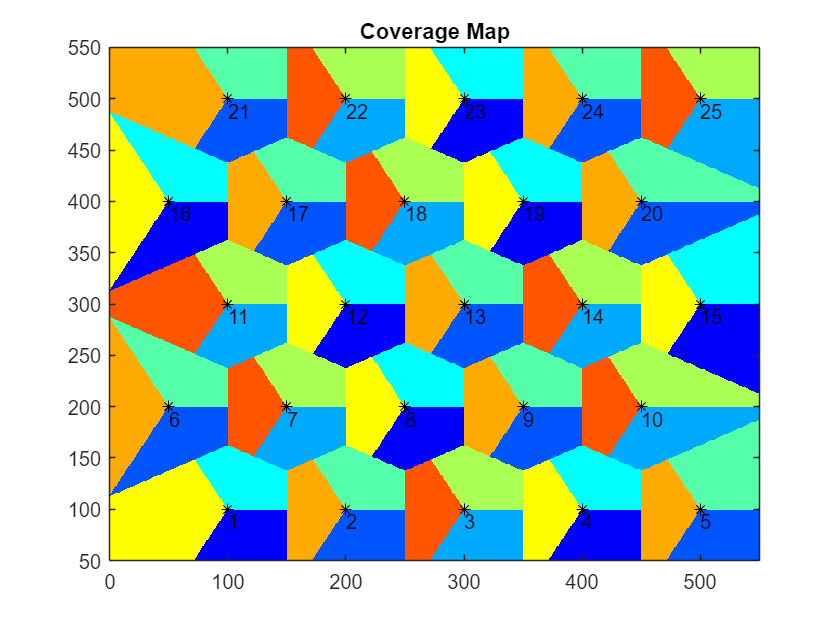



%% Set map resolution
net.map_resolution = 600;

%% Coverage Map
figure;
net.MapCoverage;
title('Coverage Map');


%% SINR Outage Map
figure;
net.MapSINR;

Covering 95.73 percent of the area with sufficient SINR
worst case SINR is 4.680901


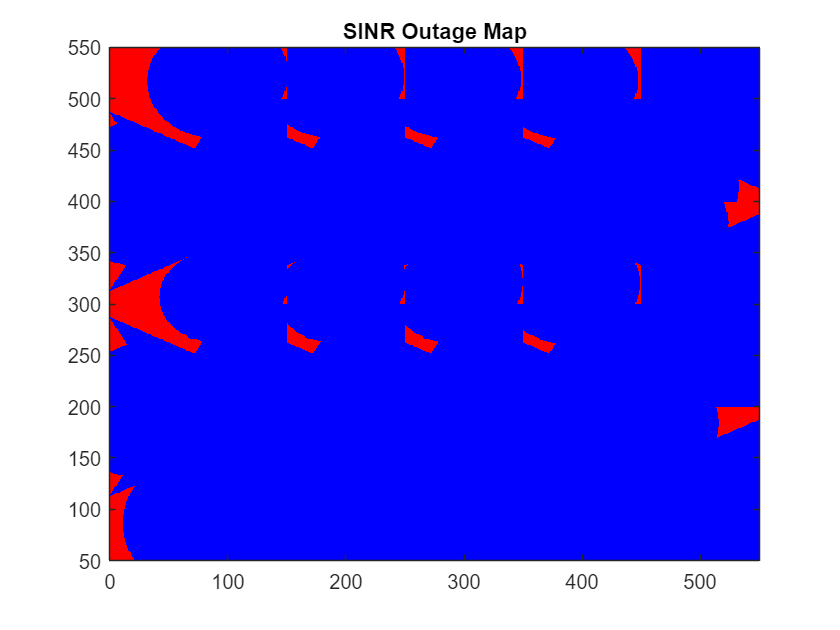

title('SINR Outage Map');

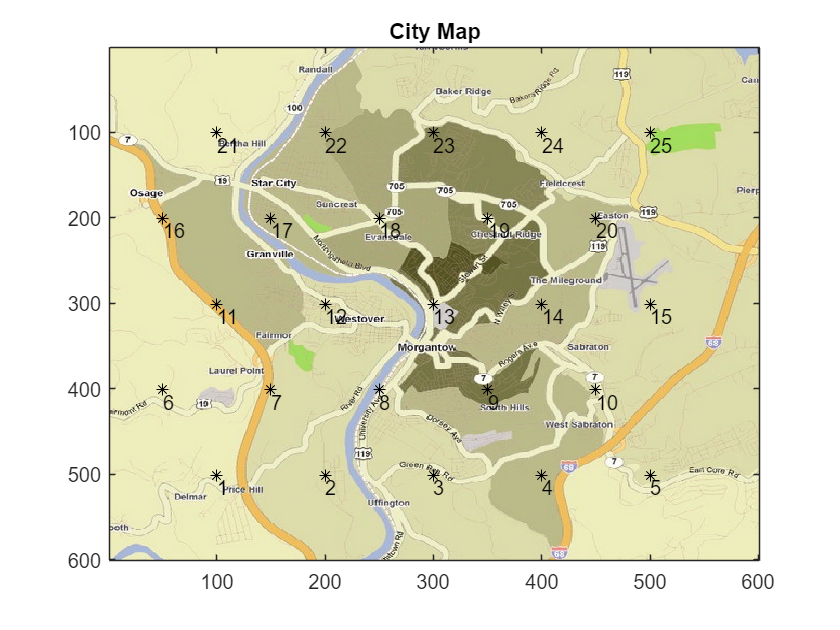


%% City Map
figure;
net.MapCity;
title('City Map');

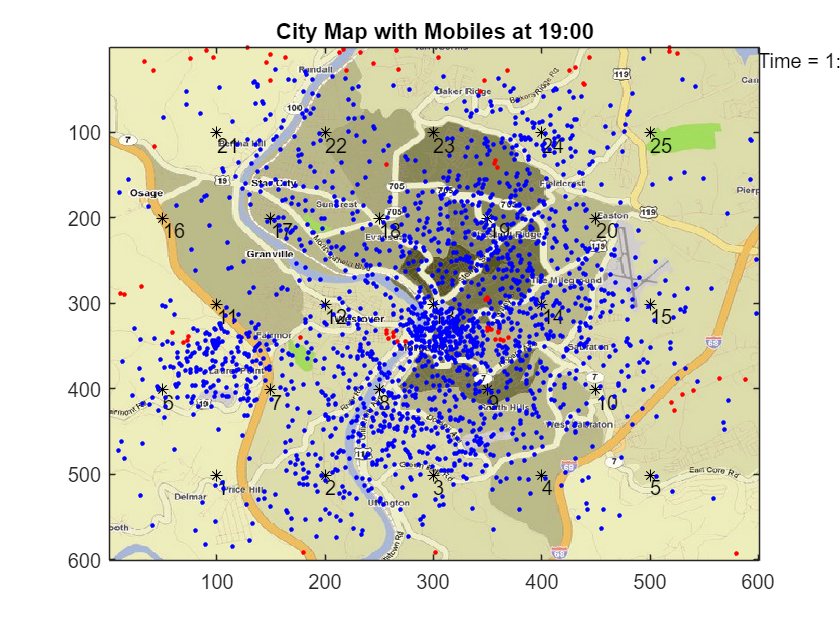


%% Load mobile locations
load('MobileLocationData');

%% City map with mobiles at 19:00
figure;
net.MapCity(ms_locations{19});
title('City Map with Mobiles at 19:00');

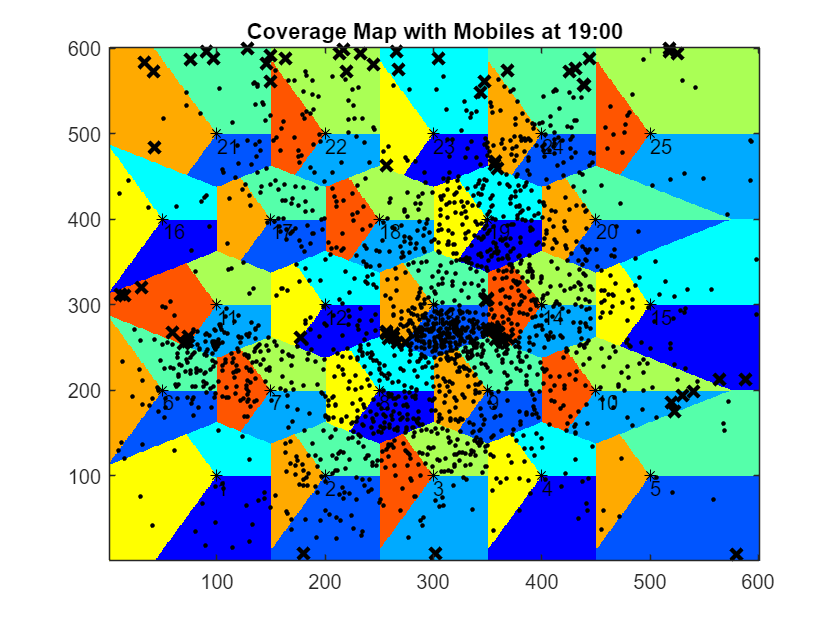


%% Coverage map with mobiles at 19:00
figure;
net.MapMobiles(ms_locations{19});
title('Coverage Map with Mobiles at 19:00');

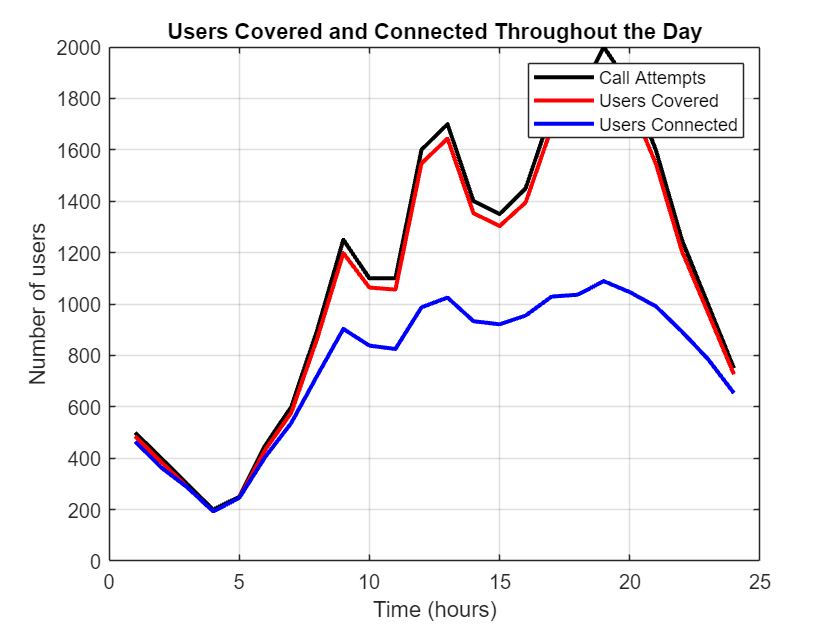


%% Analyze network performance
[num_connected, num_over_thresh] = net.AnalyzeNetwork(ms_locations);

%% Plot call attempts, covered users, and connected users
figure;
plot(1:length(call_attempts), call_attempts, '-k', ...
     1:length(call_attempts), num_over_thresh, '-r', ...
     1:length(call_attempts), num_connected, '-b','LineWidth',2);

xlabel('Time (hours)');
ylabel('Number of users');
legend('Call Attempts','Users Covered','Users Connected');
title('Users Covered and Connected Throughout the Day');
grid on;

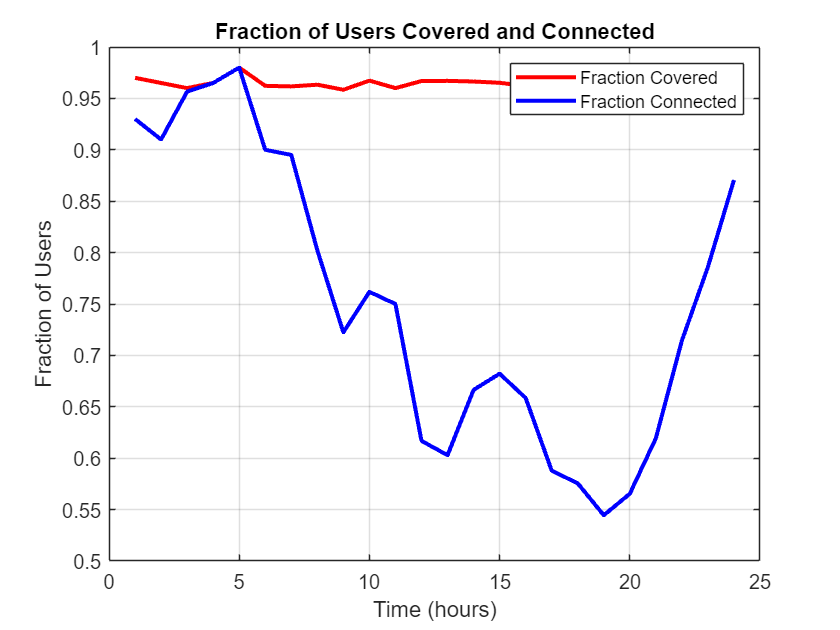


%% Fraction of users covered and connected
fraction_over_thresh = num_over_thresh ./ call_attempts;
fraction_connected = num_connected ./ call_attempts;

figure;
plot(1:length(call_attempts), fraction_over_thresh, '-r', ...
     1:length(call_attempts), fraction_connected, '-b','LineWidth',2);

xlabel('Time (hours)');
ylabel('Fraction of Users');
legend('Fraction Covered','Fraction Connected');
title('Fraction of Users Covered and Connected');
grid on;


%% KPI calculations
total_connected = sum(num_connected);
total_attempts = sum(call_attempts);

percent_connected = total_connected / total_attempts;

fprintf('\nTotal Users Connected = %d\n', total_connected);


Total Users Connected = 18128


fprintf('Total Call Attempts = %d\n', total_attempts);

Total Call Attempts = 26550


fprintf('Percentage Connected = %2.2f%%\n', 100*percent_connected);

Percentage Connected = 68.28%



%% Save the network object (.mat file required for submission)
net.Save
